# `Performance Testing / Characterization Script`

Read in JSON File for simulation configuration

clear;

david_file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
kristen_file_path = "/home/kristenangell/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
json_text = fileread(kristen_file_path + "test_config.json");
sim_config = jsondecode(json_text);
json_text_plot = fileread(kristen_file_path + "plot_config.json");
plot_config = jsondecode(json_text_plot);

Setup parameters from JSON file 

NUM_RUNS = sim_config.TestSettings.Configurations.num_runs;
FRAMES_PER_RUN = sim_config.TestSettings.Configurations.frames_per_sim;
PRE_ATTACK_FRAMES = sim_config.TestSettings.Configurations.pre_attack_frames;
MAX_BIN = sim_config.TestSettings.Configurations.max_bin;
BIN_WIDTH = sim_config.TestSettings.Configurations.bin_width;

TOTAL_FRAMES = NUM_RUNS * (FRAMES_PER_RUN-PRE_ATTACK_FRAMES);

Progress bar initialization

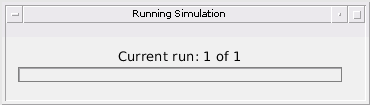

status = sprintf("Current run: %d of %d",1, NUM_RUNS);
progress_bar = waitbar(0,status,"Name","Running Simulation");

Declare the simulation

sim = Simulation_reconfigurable();
values = zeros(0,0);
raw_data = zeros(0,0);

Run simulation for NUM_RUNS, each time with different configuration

for run_idx = 1: NUM_RUNS
    status = sprintf("Current run: %d or %d",run_idx, NUM_RUNS);
%    waitbar(run_idx/NUM_RUNS,progress_bar,status);

    target_velocity = sign(randn) * randi(35)
    target_start = randi(138)+ 5;
    sim.initialize_simulation(sim_config, target_start, target_velocity);
    
    sim.run_simulation();

    [detected, actual_ranges, estimated_ranges, estimated_velocities, actual_velocities, error_ranges, error_velocities, false_positives] = sim.simulation_results();

    raw_data = [raw_data; detected', false_positives, actual_ranges', estimated_ranges, error_ranges, actual_velocities', estimated_velocities, error_velocities];

    values = [values; actual_ranges(PRE_ATTACK_FRAMES+1:end)', actual_velocities(PRE_ATTACK_FRAMES+1:end)', detected(PRE_ATTACK_FRAMES+1:end)', estimated_ranges(PRE_ATTACK_FRAMES+1:end,1), error_ranges(PRE_ATTACK_FRAMES+1:end,1), estimated_velocities(PRE_ATTACK_FRAMES+1:end,1), error_velocities(PRE_ATTACK_FRAMES+1:end,1), false_positives(PRE_ATTACK_FRAMES+1:end,1)];
end

target_velocity = 28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges =    93.1506       NaN       NaN       NaN       NaN
   94.0008       NaN       NaN       NaN       NaN
   94.8510       NaN       NaN       NaN       NaN
   95.6986       NaN       NaN       NaN       NaN
   96.5472       NaN       NaN       NaN       NaN
   95.3945   95.3947   95.3961   95.3989   95.3959
   98.6863   98.6864   98.6863   98.6849   98.6854
   99.5099   99.5093   99.5104   99.5103   99.5102
  100.5056  100.5049  100.5054  100.5054  100.5017
  101.6316  101.6299  101.6355  101.6364  101.6277


actual_ranges =    93.0000   93.8667   94.7334   95.6001   96.4668   97.3335   98.2002   99.0669   99.9336  100.8002


estimated_velocities =   -25.9651       NaN       NaN       NaN       NaN
  -25.9723       NaN       NaN       NaN       NaN
  -25.9821       NaN       NaN       NaN       NaN
  -25.9743       NaN       NaN       NaN       NaN
  -25.9607       NaN       NaN       NaN       NaN
    8.8381   39.3089   33.7161   27.7717   16.0438
   19.8009   25.0871   17.9265   -1.7383   -9.8651
   38.3965   25.9671    6.0352  -14.9432  -29.0245
    6.9800  -10.0142  -22.3511  -28.9836  -34.7531
  -39.3060   35.8487   26.2923   20.2712    9.2627


actual_velocities =    -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected =      1     1     1     1     1     0     0     0     0     0


col_detection =      1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges =     0.1506
    0.1341
    0.1176
    0.0986
    0.0805
         0
         0
         0
         0
         0


percent_error_velocities =     0.0349
    0.0277
    0.0179
    0.0257
    0.0393
         0
         0
         0
         0
         0


Organize data into table

table_graph_data = array2table(values,"VariableNames",["Range (m)","Velocity (m/s)","Detected","Estimated Range (m)", "Error Range (m)", "Estimated Velocity (m/s)", "Error Velocity (m)", "False Positives"]);
writematrix(raw_data, 'raw_data.csv');
writetable(table_graph_data,'run_table_data.csv','WriteRowNames',true); 
%track attack spoofing accuracy

### **Plot P(detection) and P(false positive) vs. Range Histogram as a sanity check for individual runs **

range_col = values(:,1);
bin_classification = cast(range_col/BIN_WIDTH, "int16")';
histogram_vals = zeros(MAX_BIN,3);
bin_counts = zeros(MAX_BIN, 3);

for bin_num = 1:MAX_BIN
    histogram_vals(bin_num, 1) = bin_num;
    count = 0;
    detected = 0;
    false_pos = 0;
    for frame = 1: TOTAL_FRAMES
        if (bin_classification(frame) == bin_num)
            count = count + 1;
            if table_graph_data{frame, 3}
                detected = detected + 1;
            end
            if table_graph_data{frame, 8}
                false_pos = false_pos + 1;
            end
        end
    end
        bin_counts(bin_num, 2) = detected;
        bin_counts(bin_num, 3) = false_pos;
    if (count ~= 0)
        histogram_vals(bin_num, 2) = detected/count;
        histogram_vals(bin_num, 3) = false_pos/count;
    end
end
bin_counts_table = array2table(bin_counts, "VariableNames", ["Bin #", "Detected Count", "False Pos. Count"])

bin_counts_table = 30×3 table
    Bin #    Detected Count    False Pos. Count
    _____    ______________    ________________

      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        


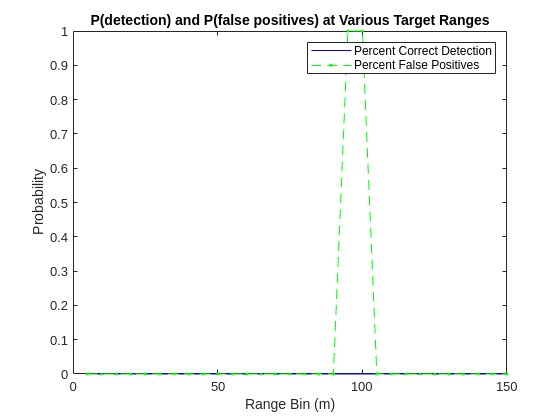

figure
plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,2), 'b');
hold on
plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,3), '--.g');
hold off
ylabel("Probability")
xlabel("Range Bin (m)")
legend("Percent Correct Detection", "Percent False Positives")
title("P(detection) and P(false positives) at Various Target Ranges")
saveas(gcf, "histogram_plot.png")

### **Plot Error vs. Range**

%% Error vs Range
range_error_plot = zeros(0,0);
for frame = 1: TOTAL_FRAMES
    val = table_graph_data{frame, 3};
    if (val(1) ~= 0)
        range_error_plot = [range_error_plot; [table_graph_data{frame, 1}, table_graph_data{frame, 5}]];
    end
end

figure
scatter(range_error_plot(:,1), range_error_plot(:,2));

Index in position 2 exceeds array bounds.

ylabel("Range Error (m)")
xlabel("Range (m)")
title("Range Error at Various Distances")
saveas(gcf, "error_plot.png")
